clear;clc;close all


t = Tiff('band1clip_Clip.tif','r');

imageData1 = read(t);
%imshow(imageData1);

%filename = uigetfile({'and7clip.tif'},'select an image file');
%Im= imread(filename);
%I = im2uint8(Im);
%imshow(I, [])

%I = imread('band7clip.tif');
%J = imadjust(I);
%imshowpair(I,J,'montage')

imageData1Col = imageData1(:);


t = Tiff('band2clip_Clip.tif','r');

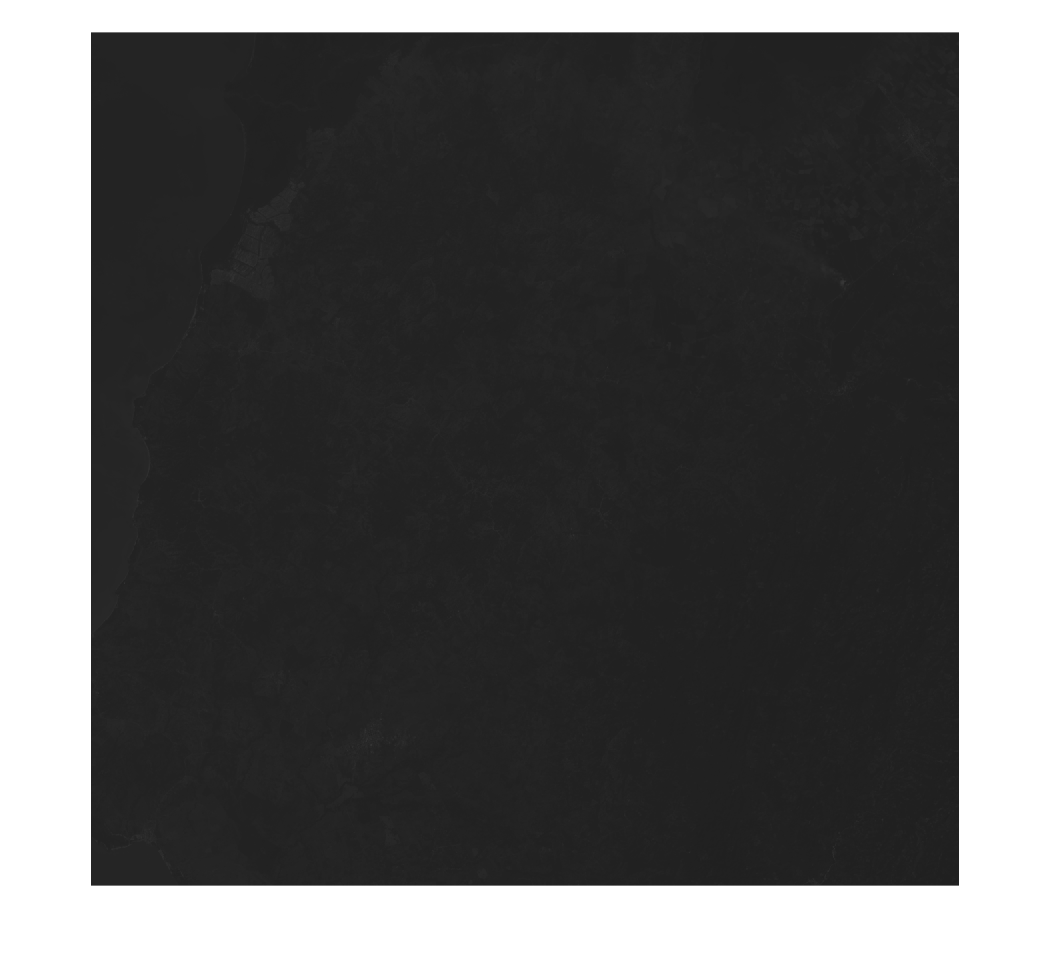

imageData2 = read(t);
imshow(imageData2);

imageData2Col = imageData2(:);

t = Tiff('band3clip_Clip.tif','r');

imageData3 = read(t);
imageData3Col = imageData3(:);

t = Tiff('band4clip_Clip.tif','r');

imageData4 = read(t);
imageData4Col = imageData4(:);

t = Tiff('band5clip_Clip.tif','r');

imageData5 = read(t);
imageData5Col = imageData5(:);

t = Tiff('band6clip_Clip.tif','r');

imageData6 = read(t);
imageData6Col = imageData6(:);

%threebands = [];
%threebands = [threebands imageData1Col(:,1) imageData2Col(:,1) imageData3Col(:,1)];
%threebands = im2double(threebands);



sixbands = [];
sixbands = [sixbands imageData1Col(:,1) imageData2Col(:,1) imageData3Col(:,1),imageData4Col(:,1) imageData5Col(:,1) imageData6Col(:,1)];
sixbands = im2double(sixbands);

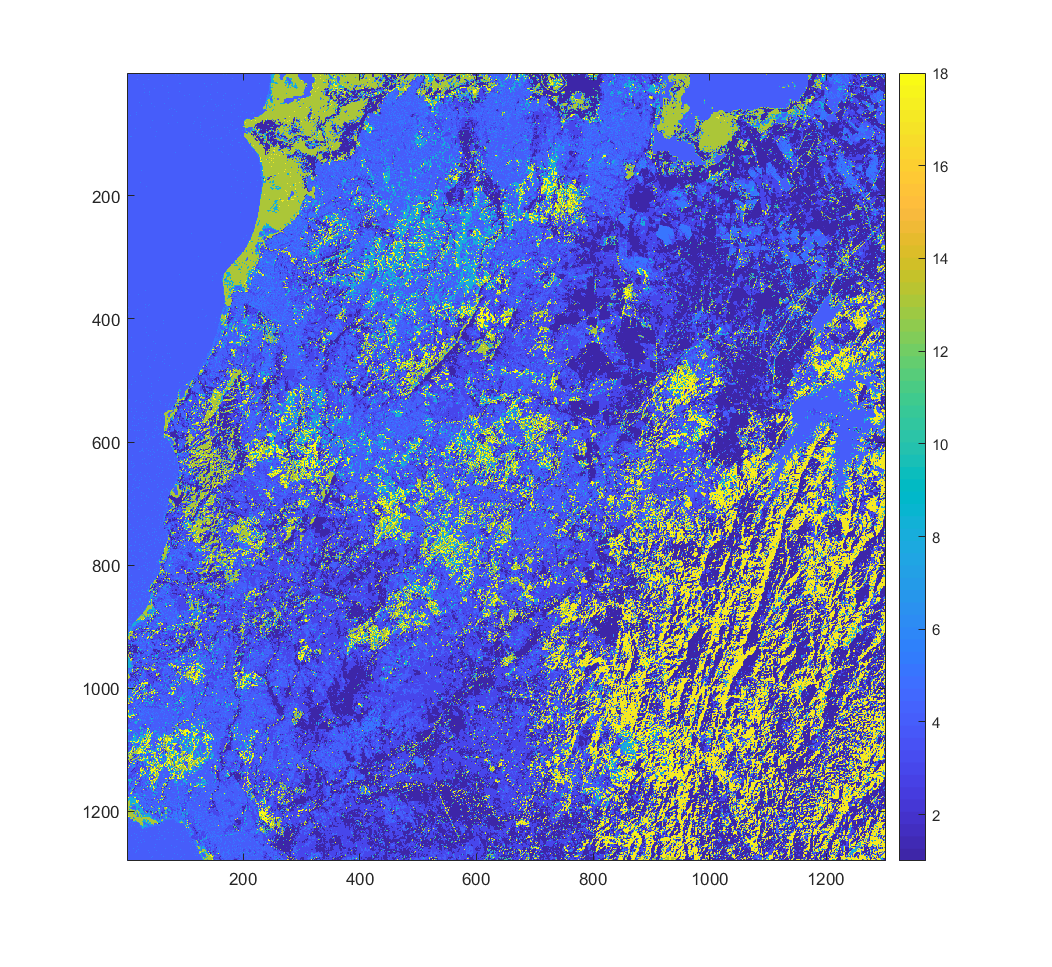



%%%%  16  3bands %%%%%%%
%net = selforgmap([4 4]);
%x = threebands';

% Train the SOM
%net = train(net,x);
%view(net)

% Use the Network to classify each record
%y16 = net(x);
%classes16 = vec2ind(y);
%imageclasses16 = reshape(classes,1280,1302);
%image(imageclasses16,"CDataMapping",'scaled');
% colorbar

%%%%  9  3 bands %%%%%%
%net = selforgmap([3 3]);
%x = threebands';
% Train the SOM
%net = train(net,x);
%view(net)

% Use the Network to classify each record
%y9 = net(x);
%classes9 = vec2ind(y9);
%imageclasses9 = reshape(classes9,1280,1302);
%image(imageclasses9,"CDataMapping",'scaled');
%colorbar



%%  


%%%%  20  6 bands %%%%%%
net = selforgmap([5,5]);
x = sixbands';

% Train the SOM
net = train(net,x);
view(net)
% Use the Network to classify each record
y320 = net(x);
classes320 = vec2ind(y320);
imageclasses320 = reshape(classes320,1280,1302);
image(imageclasses320,"CDataMapping",'scaled');
colorbar


I = imread('band3clip_Clip.tif');
J = imadjust(I);
J = im2double(J);
imshow(J,[]);
C = imfuse(imageclasses320,J);
imshow(C)

% classes observations

%forestclass = classes320;
%forestclass(forestclass ~= 1) = 0;
%forestclass(forestclass == 1) = 1;
%imageclasses20 = reshape(forestclass,1280,1302);
%image(imageclasses20,"CDataMapping",'scaled');
%C = imfuse(imageclasses20,J);
%imshow(C)

%ground = J.*imageclasses20;
%imshow(ground);

%classes merge
forestclass = classes320;
%forestclass(forestclass == 14) = 26;
%forestclass(forestclass == 16) = 26;
%forestclass(forestclass == 18) = 26;
forestclass(forestclass == 19) = 26;
%forestclass(forestclass == 20) = 26;
%forestclass(forestclass == 23) = 26;
forestclass(forestclass == 24) = 26;

forestclass(forestclass ~= 26) = 0;
forestclass(forestclass == 26) = 1;
imageclasses20 = reshape(forestclass,1280,1302);
image(imageclasses20,"CDataMapping",'scaled');
C = imfuse(imageclasses20,J);
imshow(C)

ground = J.*imageclasses20;
imshow(ground);


% forestclass = classes320;
% fullclasses = reshape(forestclass,1280,1302);
% image(fullclasses,'CDataMapping','scaled');
% fullclasses(fullclasses ~= 22) = 0;
% fullclasses(fullclasses == 22) = 1;
% mask = reshape(fullclasses,1280,1302);
% J = im2double(J);
% Inew = J.*mask;
% Inew = imadjust(Inew);
% imshow(Inew,[])



x=sixbands;
y = forestclass';

validation_fraction = 0.1;
n = length(y);
cvpart = cvpartition(n,'holdout',validation_fraction);

%Create training and testing data set
InTrain = x(training(cvpart),:);
OutTrain = y(training(cvpart),:);
n_train = length(InTrain);

InTest = x(test(cvpart),:);
OutTest = y(test(cvpart),:);

%Mdlbi = fitcensemble(InTrain,OutTrain,'Method','bag','NumLearningCycles',50);
Mdlbi = fitcensemble(InTrain,OutTrain);
%imp = oobPermutedPredictorImportance(Mdlbi);

%imp = Mdlbi.OOBPermutedPredictorDeltaError;
imp = predictorImportance(Mdlbi);
[imp_sorted,I] = sort(imp,'descend');

figure;
c1 = categorical(Mdlbi.PredictorNames);
c = c1(I);
c = c(1:6);
imp_sorted = imp_sorted(1:6);
barh(imp_sorted);
hold on;
barh(imp_sorted(1:5),'y');
barh(imp_sorted(1:3),'r');

set(gca,'xscale','log');
set(gca,'YDir','reverse');
text(imp_sorted,[1:6],char(c));
ylabel('Predictors');
xlabel('Relative Importance');
title('Predictors Importance Estimates');

%%%%% 5 confusion matrix
fit_test = predict(Mdlbi,InTest);
plotconfusion(OutTest',fit_test')


label = predict(Mdlbi,sixbands);
labelimage = reshape(label,1280,1302);
image(labelimage,"CDataMapping",'scaled');

C = imfuse(labelimage,J);
imshow(C)